% Load data
clear; clc;
% Helper functions' path
addpath('geodesy');
addpath('src')

% Note that for training we have results as well
training = false;

if training
    DIRECTORY_NUM = '1';
    MEASUREMENTS_DIR = sprintf('../datasets/round_1/%s/training_%s_category_1', DIRECTORY_NUM, DIRECTORY_NUM);
    RESULTS_DIR = sprintf('../datasets/round_1/%s/training_%s_category_1_result', DIRECTORY_NUM, DIRECTORY_NUM);

    % We have 2 sets: measurements and results (to compare our approach to)
    MEASUREMENTS_CSV = sprintf('training_%s_category_1.csv', DIRECTORY_NUM);
    SENSORS_CSV = 'sensors.csv';
    RESULTS_CSV = 'training_{}_category_1_result.csv';
    
%     BAD_SENSORS = [19]
else
    MEASUREMENTS_DIR = '../datasets/round_2';
    RESULTS_DIR = '';

    % We have 2 sets: measurements and results (to compare our approach to)
    MEASUREMENTS_CSV = 'round2_competition.csv';
    SENSORS_CSV = 'round2_sensors.csv';
    RESULTS_CSV = '';
    
%     BAD_SENSORS = [19];
end

CACHE = 'workspace_rtl.mat';

if isempty(gcp('nocreate'))
    parpool('local', 1, 'IdleTimeout', 120);
end

Starting parallel pool (parpool) using the 'local' profile ...



if isfile(sprintf('%s/%s', MEASUREMENTS_DIR, CACHE))
    load(sprintf('%s/%s', MEASUREMENTS_DIR, CACHE), 'ddoa', 'aircraft', 'sensors');
else
    f = true;
    fraction = 0.1;
    [aircraft, sensors] = loadDataRTL(MEASUREMENTS_DIR, MEASUREMENTS_CSV, SENSORS_CSV, f, fraction);
    ddoa = getddoa(aircraft);
    save(sprintf('%s/%s', MEASUREMENTS_DIR, CACHE), 'ddoa', 'aircraft', 'sensors');
end

% Speed of light is 299792458 m/s
c = 299792458;
ddoa.ddoam = ddoa.ddoa * 1e-9 * c;

backup_sensors = sensors; backup_aircraft = aircraft; backup_ddoa = ddoa;

% User this to restore everything
sensors = backup_sensors;
aircraft = backup_aircraft;
ddoa = backup_ddoa;

% % Ground truth sensor
verified = [48.09379, 11.63527, 544]; % indoor
verified = [verified; 50.7015, 8.314159, 270]; % indoor
verified = [verified; 49.850256222468396, 6.808953881263733, 230]; % outdoor
verified = [verified; 51.177688, -0.923107, 150]; % outdoor
verified = [verified; 51.1704132072078, 0.8729153479826783, 1200]; % indoor
verified = [verified; 49.12702033, 8.51932350, 125]; % outdoor
verified = [verified; 50.255839, 8.676054, 237.13]; % indoor
verified = [verified; 49.4051387, 11.1761876, 341]; % indoor

## Computing cartesian distances

For aircrafts

% Computing cartesian coordinates
xyz = llh2ecef([aircraft.latitude, aircraft.longitude, aircraft.geoAltitude]);
aircraft.x = xyz(:,1);
aircraft.y = xyz(:,2);
aircraft.z = xyz(:,3);

% % Let's obtain the coordinates of the aircraft measurements and also relate them
% % with the average positon
% center = [(quantile(aircraft.x,0.01) + quantile(aircraft.x,0.99))/2, ...
%           (quantile(aircraft.y,0.01) + quantile(aircraft.y,0.99))/2, ...
%           (quantile(aircraft.z,0.01) + quantile(aircraft.z,0.99))/2];
%       
% aircraft.x = aircraft.x - center(1);
% aircraft.y = aircraft.y - center(2);
% aircraft.z = aircraft.z - center(3);

For sensors

% Let's only keep sensors that appear on the measurements
keep = ismember(sensors.serial,ddoa.s1) | ismember(sensors.serial,ddoa.s2);
sensors = sensors(keep,:);

% Let's also compute the cartesian coordinates
xyz = llh2ecef([sensors.latitude, sensors.longitude, sensors.height]);
sensors.x = xyz(:,1); %- center(1);
sensors.y = xyz(:,2); %- center(2);
sensors.z = xyz(:,3); %- center(3);

% Radarcape 'good' sensors
reference = sensors(strcmp(sensors.good,'TRUE'),:);
% reference(BAD_SENSORS,:) = [];
unknown = sensors(strcmp(sensors.type,'dump1090'),:);

% We can compute the errors between the measured and expected TDOAs
maskddoa = ismember(ddoa.s1, sensors.serial, 'rows') & ismember(ddoa.s2, sensors.serial, 'rows');
ddoa = ddoa(maskddoa,:);

[~,acId] = ismember(ddoa.id, aircraft.id, 'rows');
[~,s1Id] = ismember(ddoa.s1, sensors.serial, 'rows');
[~,s2Id] = ismember(ddoa.s2, sensors.serial, 'rows');

acd = table2array(aircraft(acId,{'x', 'y', 'z'}));
s1d = table2array(sensors(s1Id,{'x', 'y', 'z'}));
s2d = table2array(sensors(s2Id,{'x', 'y', 'z'}));

% Computation of TDOAs
d1 = ecef_distance(acd, s1d);
d2 = ecef_distance(acd, s2d);

exp = d1 - d2;
ddoa.exp = exp;
ddoa.err = exp - ddoa.ddoam;

## Removing outliers

Some of the measurements are completely off and break the optimization.

Light travels almost 300.000 km per second.

A TDOA error of 30.000 km is not really possible (it's almost the earth circumference) so those measurements should be broken

maskerr = ddoa.err > quantile(ddoa.err,0.05) & ddoa.err < quantile(ddoa.err,0.95);
ddoa = ddoa(maskerr,:);

%%% Removing unnecessary aircrafts
unique_ids = unique(ddoa.id);
maskair = ismember(aircraft.id,unique_ids);
aircraft = aircraft(maskair,:);

% First we need to cleanup the aircrafts
% We can get the time and distance the aircraft moved while it was seen by the
% system
% Then we remove all the sensors that have wrong measurements
aircraft_list = unique(aircraft.aircraft);

max_dist = zeros(length(aircraft_list),1);
max_time = zeros(length(aircraft_list),1);
for ii = 1:length(aircraft_list)
    acId = aircraft_list(ii);
    aircraftPath = aircraft(aircraft.aircraft == acId, :);
    
    if height(aircraftPath) > 1
        max_dist(ii) = norm(table2array(aircraftPath(end,{'x','y','z'})) - table2array(aircraftPath(1,{'x','y','z'})))/1000;
        max_time(ii) = norm(table2array(aircraftPath(end,{'timeAtServer'})) - table2array(aircraftPath(1,{'timeAtServer'})));
    else
        max_dist(ii) = 0;
        max_time(ii) = 0;
    end
end

g = max_dist ~= 0;
good_aircraft = aircraft_list(g);

% Filter aircraft
maskair = ismember(aircraft.aircraft,good_aircraft);
aircraft = aircraft(maskair,:);

% Filter ddoa
maskddoa = ismember(ddoa.id,aircraft.id);
ddoa = ddoa(maskddoa,:);

## Optimization approaches (with offset)

In this one, we will use all sensors but one and optimize the position (imitating a user)

### Precomputing the offsets

The observation is that offsets remain 'constant' throughtout time, so no need to divide by aircraft or time

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%% Linear least squares    
% We start with the C matrix
maskref = ismember(ddoa.s1,reference.serial) & ismember(ddoa.s2,reference.serial);
ddoaref = ddoa(maskref,:);

maskerr = ddoaref.err > quantile(ddoaref.err,0.05) & ddoaref.err < quantile(ddoaref.err,0.95);
ddoaref = ddoaref(maskerr,:);

C = zeros(height(ddoaref), height(reference));
for index = 1:height(reference)
    s = reference.serial(index);
    mask_positive = ddoaref.s1 == s;
    mask_negative = ddoaref.s2 == s;
    
    C(mask_positive, index) = 1;
    C(mask_negative, index) = -1;
end

% Now the d vector
d = -ddoaref.err;

% We set the lower and upper bounds
sigma = std(ddoaref.err);
% lb = [-1e-7;-5*sigma.*ones(height(reference)-1,1)];
% ub = [ 1e-7; 5*sigma.*ones(height(reference)-1,1)];
lb = [-1e-7; -inf.*ones(height(reference)-1,1)];
ub = [ 1e-7;  inf.*ones(height(reference)-1,1)];

offsets = lsqlin(C,d,[],[],[],[],lb,ub);


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


reference.offsets = offsets;

### Startup options

% Optimization by fraction and sensor
% Ok, so let's set up the fractions and optimize per each one of them
% Things, that are interesting to store:
% results: (x,y,z,o,flag) 5xN_sxN_f
% time: N_sxN_f
% measurement_count: N_sxN_f (Counting how many measurements for optimization)
% Afterwards: save results, time, sensors, center

% Optimization options
options = optimoptions('fminunc','Display','final','Algorithm','trust-region',...
                       'SpecifyObjectiveGradient',true,'UseParallel',true,'MaxIterations',3000,...
                       'MaxFunctionEvaluations', 30000, 'StepTolerance',1e-19, 'OptimalityTolerance',1e-19);

sensorIds = [607, 578, 363, 463, 357, 584, 83, 614];

SELECT = 1;

%% Data preparation
sensor = unknown(unknown.serial == sensorIds(SELECT),:);

%% Selecting by policy
mask = (ddoa.s1 == sensor.serial) | (ddoa.s2 == sensor.serial);
maskg = (ismember(ddoa.s1,reference.serial) | ismember(ddoa.s2,reference.serial));
mask = mask & maskg;

%% TODO: Move the selection policy to a function
% For now, we will use the most common sensors as ground
ddoa_sensor_count = grpstats(ddoa(mask,:),{'s1','s2'});
ddoa_sensor_count = sortrows(ddoa_sensor_count,'GroupCount','descend');

### Selecting sensors and references

% Loop parameters
numIter = 1; % Iterations per fraction and sensor
num_ref = 2; % Max number of reference sensors to use

Ng = min([height(ddoa_sensor_count), num_ref]);

indices = zeros(Ng,1);
for jj = 1:Ng
    if ddoa_sensor_count.s1(jj) == sensor.serial
        indices(jj) = find(reference.serial == ddoa_sensor_count.s2(jj));
    else
        indices(jj) = find(reference.serial == ddoa_sensor_count.s1(jj));
    end
end
ground = reference(indices,:);
% ground = ground(2:end,:);
ground.drift = zeros(height(ground),1);

% Let's filter the data
mask_s = ismember(ddoa.s1, sensor.serial, 'rows') | ismember(ddoa.s2, sensor.serial, 'rows');
mask_g = ismember(ddoa.s1, ground.serial, 'rows') | ismember(ddoa.s2, ground.serial, 'rows');
mask_s = mask_s & mask_g;
data = ddoa(mask_s,:);
data = sortrows(data,'id');

dt = sortrows(data,'id');

% We need the mean positions
unique_id = unique(data.id);
[~,idx,~] = intersect(aircraft.id,unique_id);
ac = aircraft(idx,:);

% Just filter number of aircraft
FILTER = 100; OFFSET=1;
ac_f = ac(OFFSET:OFFSET+FILTER-1,:);
[Ids,~] = ismember(dt.id, ac_f.id, 'rows');
dt = dt(Ids,:);

% Add some centering
center = mean([ac_f.x, ac_f.y, ac_f.z],1);

ground.xc = ground.x - center(1);
ground.yc = ground.y - center(2);
ground.zc = ground.z - center(3);

ac_f.xc = ac_f.x - center(1);
ac_f.yc = ac_f.y - center(2);
ac_f.zc = ac_f.z - center(3);

% Initial pos
mean_llh = mean([ground.latitude, ground.longitude, ground.height],1);
% p0.x = mean(ground.x);
% p0.y = mean(ground.y);
% p0.z = mean(ground.z);
r = llh2ecef(mean_llh);
p0.x = r(1); p0.y = r(2); p0.z = r(3);
p0.xc = p0.x - center(1);
p0.yc = p0.y - center(2);
p0.zc = p0.z - center(3);

### Initial estimations

% Let's estimate the offset and the drift from the data
sensortmp = sensor;
sensortmp.x = p0.x;
sensortmp.y = p0.y;
sensortmp.z = p0.z;
sensortmp.xc = p0.xc;
sensortmp.yc = p0.yc;
sensortmp.zc = p0.zc;
sensortmp.offsets = 0;
sensortmp.drift = 0;
comb = [sensortmp;ground];

[~,acId] = ismember(dt.id, ac_f.id, 'rows');
[~,s1Id] = ismember(dt.s1, comb.serial, 'rows');
[u1Id,~] = ismember(dt.s1, sensortmp.serial, 'rows');
[~,s2Id] = ismember(dt.s2, comb.serial, 'rows');
[u2Id,~] = ismember(dt.s2, sensortmp.serial, 'rows');

acd = table2array(ac_f(acId,{'xc', 'yc', 'zc'}));
s1d = table2array(comb(s1Id,{'xc', 'yc', 'zc'}));
s2d = table2array(comb(s2Id,{'xc', 'yc', 'zc'}));

% Computation of TDOAs
d1 = ecef_distance(acd, s1d);
d2 = ecef_distance(acd, s2d);

exp = d1 - d2;
res = exp - dt.ddoam;

if any(u2Id)
    res(u2Id) = -res(u2Id);
end
    
t = ac_f.timeAtServer(acId);
X = [ones(length(t),1), t];
beta = X\res;
b = robustfit(t,res);

% err = res - (beta(1)+beta(2).*(t-min(t)));
err = res - (b(1)+b(2).*(t-min(t)));
maskr = err > quantile(err,0.05) & err < quantile(err,0.95);
dtm = dt(maskr,:);
tm = t(maskr,:);
delta_tm = tm - min(tm);
acm = ac_f(ismember(ac_f.id,dtm.id),:);

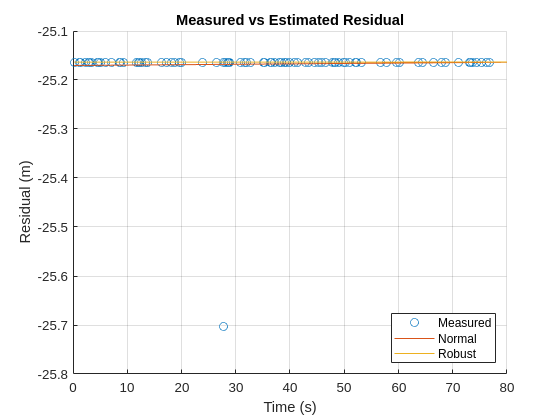

% Plot differences
figure(); hold on; grid on;
scatter(t, res/c);
plot(t, (t*beta(2)+beta(1))/c); % Unrobust
plot(t, (t*b(2)+b(1))/c); % Robust
xlabel('Time (s)');
ylabel('Residual (m)');
legend('Measured', 'Normal', 'Robust','Location','southeast');
title('Measured vs Estimated Residual');
xlim([0, 80]);
zlim([-1.00 1.00]);
hold off;

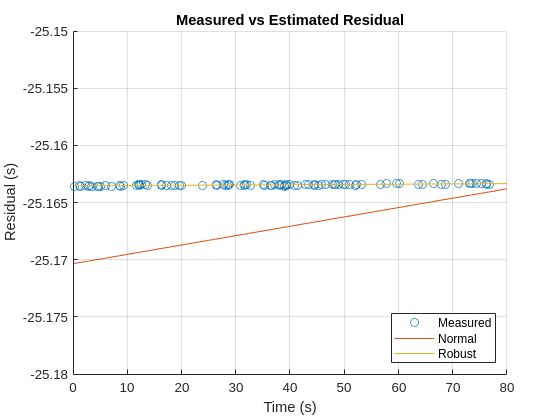

% Plot differences
figure(); hold on; grid on;
scatter(t, res/c);
plot(t, (t*beta(2)+beta(1))/c); % Unrobust
plot(t, (t*b(2)+b(1))/c); % Robust
xlabel('Time (s)');
ylabel('Residual (s)');
legend('Measured', 'Normal', 'Robust','Location','southeast');
title('Measured vs Estimated Residual');
xlim([0, 80])
ylim([-25.18, -25.15]);
zlim([-1.00 1.00])
hold off;

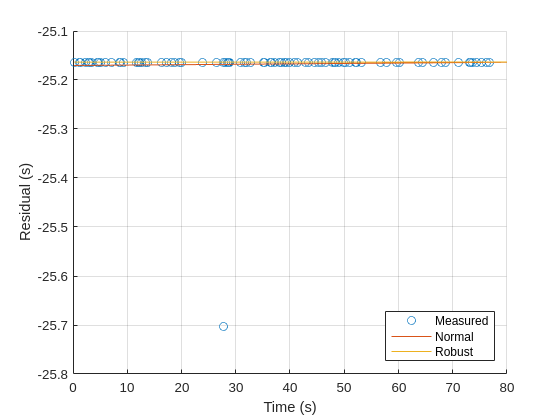

% Remove very far away aircraft

xyz_ac = acm(:,{'x','y','z'});
xyz_ss = sensortmp(:,{'x','y','z'});
d_to_sensor = ecef_distance(table2array(xyz_ac), table2array(xyz_ss));
k_ids = d_to_sensor < 4e5;
acm = acm(k_ids,:);
ac_ll = table2array(acm(:,{'latitude','longitude'}));

EVA = evalclusters(ac_ll,'linkage',"silhouette","KList",[5:30])

EVA =   SilhouetteEvaluation with properties:

    NumObservations: 90
         InspectedK: [5 6 7 8 9 10 11 12 13 14 15 16 17 18 19 20 21 22 23 24 25 26 27 28 29 30]
    CriterionValues: [0.6467 0.6557 0.7104 0.8119 0.8407 0.8422 0.8701 0.8391 0.8260 0.8473 0.8696 0.8511 0.8535 0.8492 0.8501 0.8449 0.8308 0.8379 0.8528 0.8186 0.8279 0.8281 0.8219 0.8538 0.8476 0.8575]
           OptimalK: 11


k = EVA.OptimalK;
% k = height(ac_ll);
ac_ll = table2array(acm(:,{'latitude','longitude'}));
[~, centroids] = kmeans(ac_ll, k);

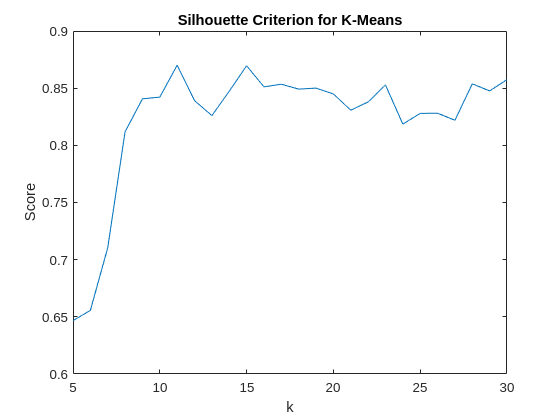

figure(); grid on;
plot(EVA.InspectedK, EVA.CriterionValues);
title('Silhouette Criterion for K-Means');
xlabel('k');
ylabel('Score');

distances = inf * ones(k,size(ac_ll,1));
for ii = 1:size(ac_ll,1)
    distances(:,ii) = sum((centroids - ac_ll(ii,:)).^2,2);
end

[val, idx] = min(distances,[],2);
selected_ac = acm(idx,:);
selected_ac = sortrows(selected_ac,'id');
dt_ids = ismember(dtm.id, selected_ac.id, 'rows');
selected_dt = dtm(dt_ids,:);
selected_delta = delta_tm(dt_ids);

### Non Linear Optimization

## Now that we have the offsets let's start with the real optimization

% Initial position
x0 = [p0.xc; p0.yc; p0.zc; -beta(1); -beta(2)];

fun = @(x) minimizeroffsetdrift(x(1), x(2), x(3), x(4), x(5), sensor.serial, selected_delta, selected_ac, selected_dt, ground(:,{'xc','yc','zc','offsets','drift', 'serial'}));

[position,fval,flag] = fminunc(fun,x0,options);


Local minimum possible.

fminunc stopped because the final change in function value relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>


solutionllh = ecef2llh(position(1:3)'+center)

solutionllh = 	1.0e+03 *

    0.0507    0.0083    1.6555


realpos = table2array(sensor(1,{'latitude','longitude','height'}));
vdist(solutionllh(1), solutionllh(2), realpos(1), realpos(2))

ans = 199.2044

initial = ecef2llh([p0.xc, p0.yc, p0.zc]+center)

initial =    48.9477   11.1922  399.9129


havdist(initial, table2array(sensor(1,{'latitude','longitude','height'})))

ans = 5.0941e+04

norobust = [339.60, 133.08, 71.65, 241.42, 73.72, 44.48, 37.83, 1140.12];
withrobust = [18.0678, 121.1023, 25.5907, 209.2381, 196.8072, 25.6305, 26.5766, 35.6367];
withkmeans = [31.5254  126.3244   34.5764  219.2082  203.4116   51.1677   46.7740   64.9834];

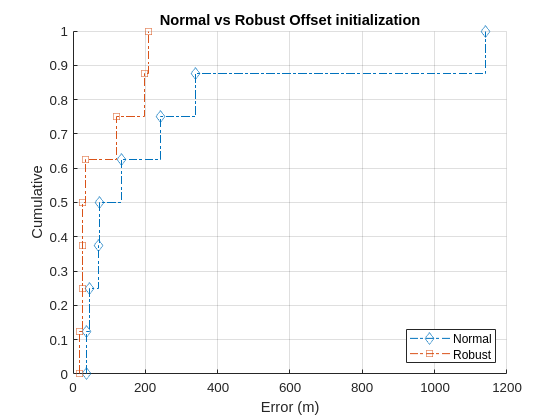

figure(); grid on; hold on;
styles = {'d-.', 's-.', 'o-.', '^-.', 'p-.'};
[f1,x1] = ecdf(norobust); 
[f2,x2] = ecdf(withrobust);
stairs(x1, f1, styles{1}); stairs(x2, f2, styles{2});
legend('Normal', 'Robust','Location','southeast');
title('Normal vs Robust Offset initialization');
xlabel('Error (m)');
ylabel('Cumulative');

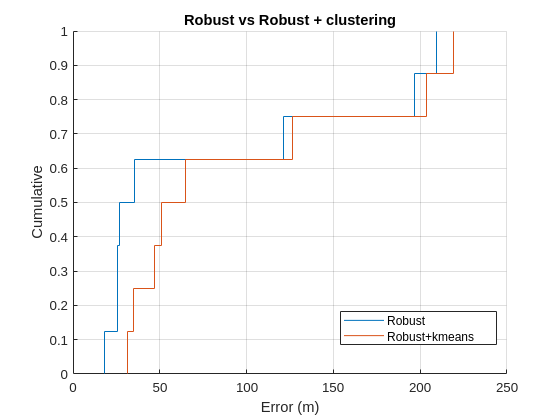

figure(); grid on; hold on;
[f1,x1] = ecdf(withrobust); 
[f2,x2] = ecdf(withkmeans);
stairs(x1, f1); stairs(x2, f2);
legend('Robust', 'Robust+kmeans');
title('Robust vs Robust + clustering');
xlabel('Error (m)');
ylabel('Cumulative');

legend('Position',[0.62381,0.17817,0.24821,0.082143])

### Plotting

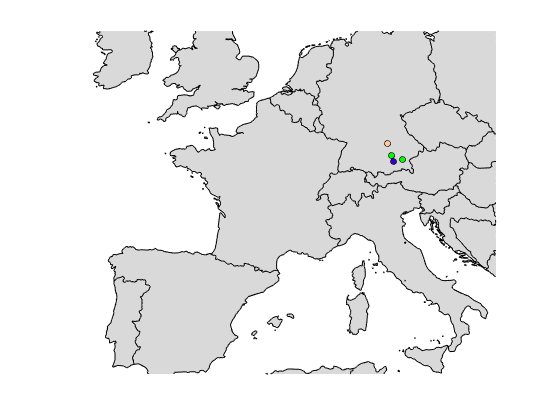

figure
ax = worldmap([20 70],[-30 40]);
hold on
setm(ax, 'MapProjection',"mercator", 'Frame',"off", 'Grid',"off")
%% zoom in
ax.XLim = [-1.7846e+06 1.5681e+06];
ax.YLim = [4.3808e+06 7.1748e+06];
% plot borders / lands
geoshow(ax, 'shapefiles/CNTR_RG_10M_2016_4326.shp', 'FaceColor',[0.85 0.85 0.85]);
% plot good sensor locations (green dots)
scatterm(ground.latitude, ground.longitude, 20, [0,1.0,0], 'filled', 'MarkerEdgeColor',[0.0, 0.0, 0.0]);
scatterm(sensor.latitude, sensor.longitude, 20, [1.0,0,0], 'filled', 'MarkerEdgeColor',[0.0, 0.0, 0.0]);
scatterm(initial(1), initial(2), 20, [1.0,.8,.6], 'filled', 'MarkerEdgeColor',[0.0, 0.0, 0.0]);
h = scatterm(solutionllh(1), solutionllh(2), 20, [0,0,1.0], 'filled', 'MarkerEdgeColor',[0.0, 0.0, 0.0]);
h.Children.MarkerFaceAlpha = .8;

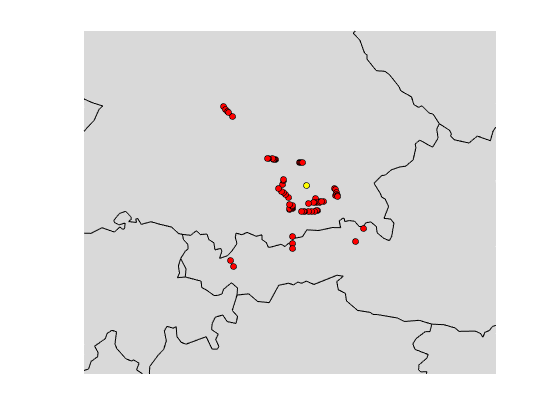

% All aircraft
figure
ax = worldmap([20 70],[-30 40]);
hold on
setm(ax, 'MapProjection',"mercator", 'Frame',"off", 'Grid',"off")
%% zoom in
ax.XLim = [-1.7846e+06 1.5681e+06];
ax.YLim = [4.3808e+06 7.1748e+06];
% plot borders / lands
geoshow(ax, 'shapefiles/CNTR_RG_10M_2016_4326.shp', 'FaceColor',[0.85 0.85 0.85]);
scatterm(acm.latitude, acm.longitude, 20, [1.0,0.0,0.0], 'filled', 'MarkerEdgeColor',[0.0, 0.0, 0.0]);
scatterm(sensor.latitude, sensor.longitude, 20, [1.0,1.0,0], 'filled', 'MarkerEdgeColor',[0.0, 0.0, 0.0]);

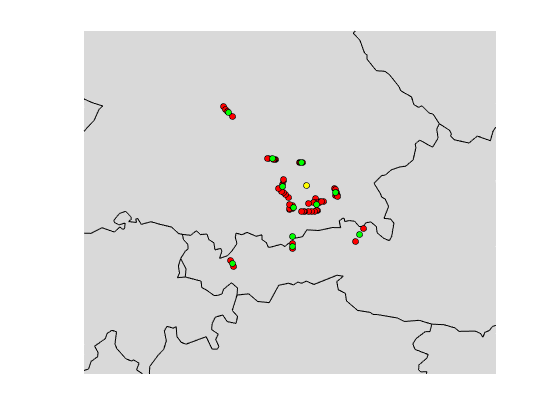

% Kmeans clustering
figure
ax = worldmap([20 70],[-30 40]);
hold on
setm(ax, 'MapProjection',"mercator", 'Frame',"off", 'Grid',"off")
%% zoom in
ax.XLim = [-1.7846e+06 1.5681e+06];
ax.YLim = [4.3808e+06 7.1748e+06];
% plot borders / lands
geoshow(ax, 'shapefiles/CNTR_RG_10M_2016_4326.shp', 'FaceColor',[0.85 0.85 0.85]);
scatterm(acm.latitude, acm.longitude, 20, [1.0,0.0,0.0], 'filled', 'MarkerEdgeColor',[0.0, 0.0, 0.0]);
scatterm(centroids(:,1), centroids(:,2), 20, [0.0,1.0,0.0], 'filled', 'MarkerEdgeColor',[0.0, 0.0, 0.0]);
scatterm(sensor.latitude, sensor.longitude, 20, [1.0,1.0,0], 'filled', 'MarkerEdgeColor',[0.0, 0.0, 0.0]);
xlim([325116 1087538])
ylim([5765581 6400952])

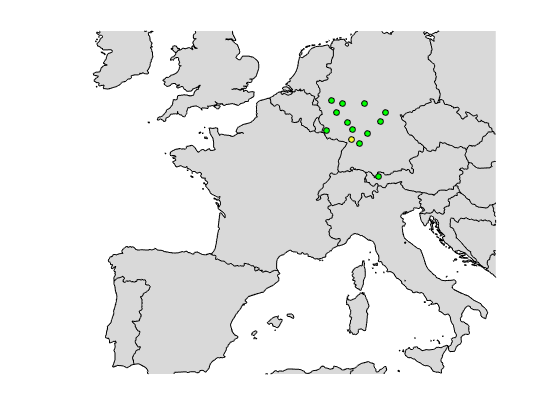

% Selected aircraft after clustering
figure
ax = worldmap([20 70],[-30 40]);
hold on
setm(ax, 'MapProjection',"mercator", 'Frame',"off", 'Grid',"off")
%% zoom in
ax.XLim = [-1.7846e+06 1.5681e+06];
ax.YLim = [4.3808e+06 7.1748e+06];
% plot borders / lands
geoshow(ax, 'shapefiles/CNTR_RG_10M_2016_4326.shp', 'FaceColor',[0.85 0.85 0.85]);
scatterm(selected_ac.latitude, selected_ac.longitude, 20, [0.0,1.0,0.0], 'filled', 'MarkerEdgeColor', [0.0, 0.0, 0.0]);
h = scatterm(sensor.latitude, sensor.longitude, 20, [1.0,1.0,0], 'filled', 'MarkerEdgeColor',[0.0, 0.0, 0.0]);
h.Children.MarkerFaceAlpha = .8;

## Some tests with hierarchical clustering


EVA = evalclusters(ac_ll, "linkage", "silhouette","KList",[5:30])

EVA =   SilhouetteEvaluation with properties:

    NumObservations: 90
         InspectedK: [5 6 7 8 9 10 11 12 13 14 15 16 17 18 19 20 21 22 23 24 25 26 27 28 29 30]
    CriterionValues: [0.6467 0.6557 0.7104 0.8119 0.8407 0.8422 0.8701 0.8391 0.8260 0.8473 0.8696 0.8511 0.8535 0.8492 0.8501 0.8449 0.8308 0.8379 0.8528 0.8186 0.8279 0.8281 0.8219 0.8538 0.8476 0.8575]
           OptimalK: 11


Z = linkage(ac_ll);
cl = cluster(Z,'maxclust',11);

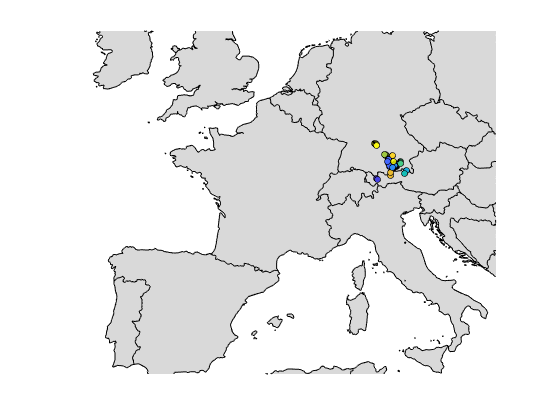

% Hierarchical clustering
figure
ax = worldmap([20 70],[-30 40]);
hold on
setm(ax, 'MapProjection',"mercator", 'Frame',"off", 'Grid',"off")
%% zoom in
ax.XLim = [-1.7846e+06 1.5681e+06];
ax.YLim = [4.3808e+06 7.1748e+06];
% plot borders / lands
geoshow(ax, 'shapefiles/CNTR_RG_10M_2016_4326.shp', 'FaceColor',[0.85 0.85 0.85]);
scatterm(acm.latitude, acm.longitude, 20, cl, 'filled', 'MarkerEdgeColor',[0.0, 0.0, 0.0]);
h = scatterm(sensor.latitude, sensor.longitude, 20, [1.0,1.0,0], 'filled', 'MarkerEdgeColor',[0.0, 0.0, 0.0]);
h.Children.MarkerFaceAlpha = .8;